# CISC271, Winter 2024, Week 7, Day 1A: k-Means Clustering

## Test Data

% Recall the test dataset
testGrades = [30 22 28;...
    20 18 19;...
    31 22 27;...
    28 23 28;...
    33 30 36]

testGrades =     30    22    28
    20    18    19
    31    22    27
    28    23    28
    33    30    36


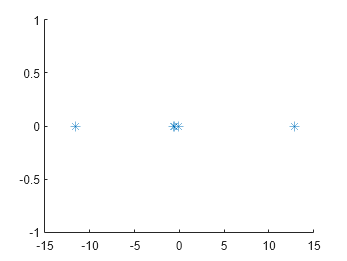


% Currently, this dataset is represented in 3 dimensions (each feature/test
% is a dimension, OR it takes 3 pieces of information to describe the students performance)

% In week 5 we saw how we can use PCA to reduce the data to 1 dimension.
testGradesM = testGrades - mean(testGrades); %Step 1: zero-mean the data
[U, S, V] = svd(testGradesM); %Step 2: perform SVD
Z1 = testGradesM*V(:,1); %Step 3: find PCA scores
Z2 = testGradesM*V(:,2); %Step 3: find PCA scores

% When we visualize the PCA score of each student, we see 3 groups produced
% which we described as high performing, average performing, low performing.
scatter(Z1, zeros(5,1), 60, '*')


% Q: Is there  a way we can computationally find the 3 groups of students?
% A: Yes, unsupervised learning.


## Clustering test grades

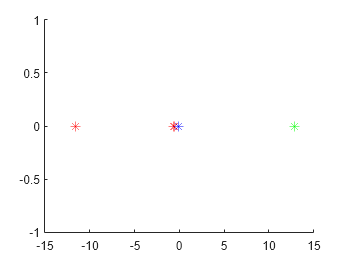

% K-means clustering is an example of unsupervised learning. 
% Def: unsupervised learning is learning patterns in data without knowing
% the true data label

% K-means clustering tries to find clusters using centroids. 
% Step 1: select k points which will be centroids c1, c2,.. ck
% Step 2: measure the distance of each pca score to each centroid.
% Step 3: assign each data point to the centroid it is closer to, ci, placing
% it in cluster i.
% Step 4: Calculate the centroid of each cluster based on the datapoints.
% Step 5: repeat step 2-4 until some condition is met (ex. points stop
% changing which cluster they are assigned to).

% There is a random element to kmeans: what is the first guess for c1, ...
% ck? MATLAB kmeans algorithm follows the kmeans++ algorithm (can be found
% in kmeans documentation) where each centroid is a data point selected at
% random from different distributions. 

% You will be using MATLAB kmeans algorithm in your assignment so you do
% not have to code it yourself however, it can be a useful exercise to do
% so to understand the algorithm.

% Lets use students 1,2 and 4 as our centroids.
c1 = Z1(1);
c2 = Z1(2);
c3 = Z1(4);

% Step 1:
% calculate the distance of each pca score to each centroid.
distances = zeros(5,3); % each row is a student and each column will hold the distance to each of the 3 centroids.
distances(:, 1) = pdist2(Z1, c1);
distances(:, 2) = pdist2(Z1, c2);
distances(:, 3) = pdist2(Z1, c3);

%determine which cluster each point belongs to.
[~, clusters] = min(distances, [], 2); %find the column # of the smallest distance in each row of distances

colorMat = zeros(5,3);
colorMat(clusters == 1, 1) = 1; % assign group 1 to red
colorMat(clusters == 2, 2) = 1; % assign group 2 to green
colorMat(clusters == 3, 3) = 1; % assign group 3 to blue

scatter(Z1, zeros(5,1), 60, colorMat, '*')


%Step 2:
%re-calculate the centroids
c1 = mean(Z1(clusters == 1)) % new c1 is centroid of points assigned to cluster 1

c1 = -4.2765

c2 = mean(Z1(clusters == 2)) % new c2 is centroid of points assigned to cluster 2

c2 = 12.8881

c3 = mean(Z1(clusters == 3)) % new c3 is centroid of points assigned to cluster 3

c3 = -0.0587

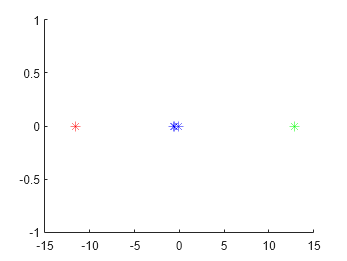


% calculate the distance of each pca score to each centroid.
distances = zeros(5,3); % each row is a student and each column will hold the distance to each of the 3 centroids.
distances(:, 1) = pdist2(Z1, c1);
distances(:, 2) = pdist2(Z1, c2);
distances(:, 3) = pdist2(Z1, c3);

%determine which cluster each point belongs to.
%find the column # of the smallest distance in each row of distances
[~, clusters] = min(distances, [], 2); 
colorMat = zeros(5,3);
colorMat(clusters == 1, 1) = 1; % assign group 1 to red
colorMat(clusters == 2, 2) = 1; % assign group 2 to green
colorMat(clusters == 3, 3) = 1; % assign group 3 to blue

scatter(Z1, zeros(5,1), 60, colorMat, '*')

## Use MATLAB kmeans on 1D data

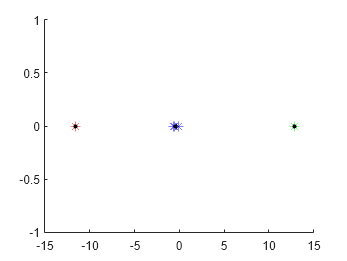

% we can do this in a single MATLAB call. Remember, the cluster numbers are
% randomy assigned, all that matters is which points are in the same
% cluster.

% Assign the points in Z1 to 3 clusters
[clusters, centroids] = kmeans(Z1, 3); 

%find the column # of the smallest distance in each row of distances
[~, clusters] = min(distances, [], 2); 
colorMat = zeros(5,3);
colorMat(clusters == 1, 1) = 1; % assign group 1 to red
colorMat(clusters == 2, 2) = 1; % assign group 2 to green
colorMat(clusters == 3, 3) = 1; % assign group 3 to blue

scatter(Z1, zeros(5,1), 60, colorMat, '*')
hold on;

% Visualize centroids found by kmeans as black dots
scatter(centroids, zeros(3,1), 100, 'k.')
hold off;

## Use MATLAB kmeans on 2D data

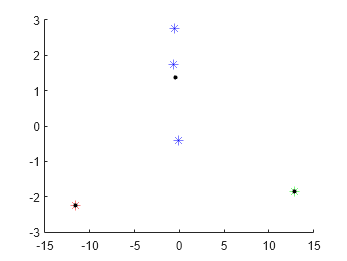

% Repeat the process on 2D PCA

% Assign the points in Z1 to 3 clusters
[clusters, centroids] = kmeans([Z1 , Z2], 3); 

% Find the column # of the smallest distance in each row of distances
[~, clusters] = min(distances, [], 2); 
colorMat = zeros(5,3);
colorMat(clusters == 1, 1) = 1; % assign group 1 to red
colorMat(clusters == 2, 2) = 1; % assign group 2 to green
colorMat(clusters == 3, 3) = 1; % assign group 3 to blue

scatter(Z1, Z2, 60, colorMat, '*')
hold on;

% Visualize centroids found by kmeans as black dots
scatter(centroids(:,1), centroids(:,2), 100, 'k.')
hold off;